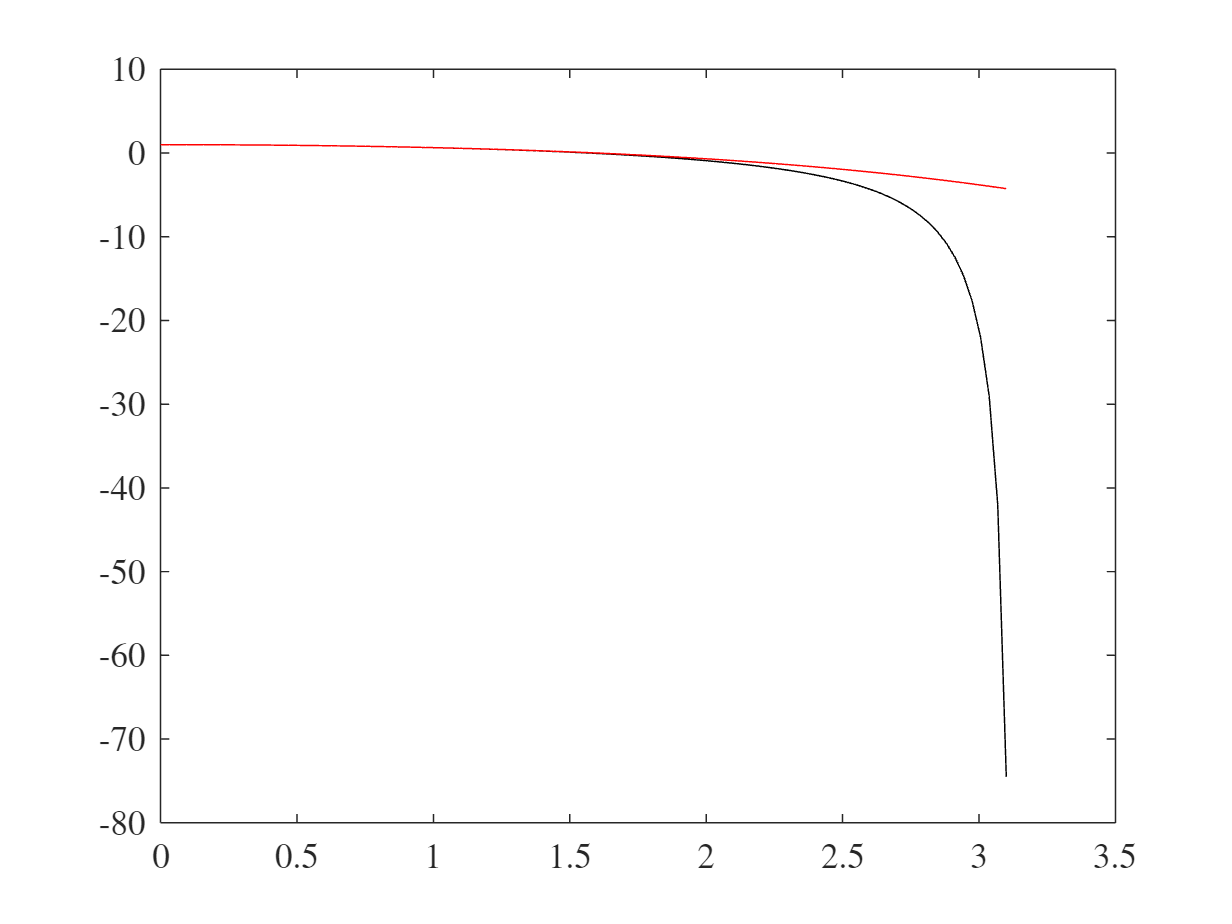

clear

GA = 1;
GB = 1;

func = @(x) (GA*GB*x^2 - 36) / 6 / (GA+GB) - x / tan(x);

xdomain = linspace(eps, 3.1, 100);

for ii = 1 : length(xdomain)
    x = xdomain(ii);
    y(ii) = func(x);
    y1(ii) = x / tan(x);
    y2(ii) = 1 - x^2 / 3 - x^4 / 45;

end

plot(xdomain, y1, 'k', xdomain, y2, 'r')


% ylim([-5 5])

